%% quaternion_rotation_plot.m
% Скрипт: поворот вектора кватернионом и 3D-визуализация

clear; clc; close all;


%% 2) Задаём параметры вращения
u = [0, 0, 1];    % ось вращения (единичный вектор)
theta = pi/2;         % угол = 60° в радианах

% формируем единичный кватернион вращения
u = u / norm(u);
q = [ cos(theta/2), sin(theta/2)*u ];

%% 3) Исходный вектор и его поворот
v      = [1, 0, 0];       % исходный вектор
v_rot  = quatRotate(q, v);% повернутый вектор

fprintf('Исходный вектор:    [%g, %g, %g]\n', v);

Исходный вектор:    [1, 0, 0]


fprintf('Повернутый вектор:  [%g, %g, %g]\n', v_rot);

Повернутый вектор:  [2.22045e-16, 1, 0]


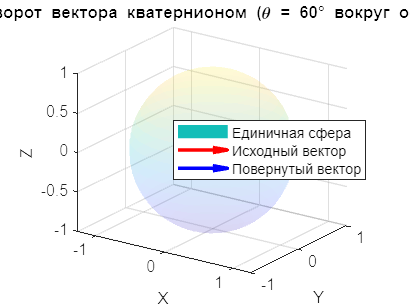


%% 4) Построение 3D-графика
figure('Color','w');
hold on; grid on; axis equal;

% единичная сфера для ориентира
[sX,sY,sZ] = sphere(24);
surf(sX, sY, sZ, 'FaceAlpha',0.1, 'EdgeColor','none');

% векторы
quiver3(0,0,0, v(1),   v(2),   v(3),   0, 'r', 'LineWidth',2, 'MaxHeadSize',0.5);
quiver3(0,0,0, v_rot(1), v_rot(2), v_rot(3), 0, 'b', 'LineWidth',2, 'MaxHeadSize',0.5);

% подписи и вид
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('Единичная сфера','Исходный вектор','Повернутый вектор','Location','best');
title('Поворот вектора кватернионом (\theta = 60° вокруг оси Z)');
view(35,20);

hold off;






%% 1) Определим вспомогательные функции
% Умножение кватернионов q * p

function r = quatMul(q, p)
    w1 = q(1); v1 = q(2:4);
    w2 = p(1); v2 = p(2:4);
    w  = w1*w2 - dot(v1,v2);
    v  = w1*v2 + w2*v1 + cross(v1,v2);
    r  = [w, v];
end

% Сопряжение кватерниона
function qc = quatConj(q)
    qc = [q(1), -q(2), -q(3), -q(4)];
end

% Обратный кватернион q^{-1} = conj(q) / norm(q)^2
function qi = quatInv(q)
    qi = quatConj(q) / (norm(q)^2);
end

% Поворот вектора v кватернионом q: v' = q * [0 v] * q^{-1}
function v_rot = quatRotate(q, v)
    qv    = [0, v(:).'];
    q_out = quatMul( quatMul(q, qv), quatInv(q) );
    v_rot = q_out(2:4);
end